# Task 4:

% checking the controllability and observability of the system
numG = 1;
denG = conv(conv([1 0], [1 1]),[0.2 1]);
% conversion to state-space
[Ag,Bg,Cg,Dg] = tf2ss(numG,denG);
system_order = length(Ag)

system_order = 3

M = ctrb(Ag,Bg); % computing controllability matrix
rank_of_M = rank(M)

rank_of_M = 3

N = obsv(Ag,Cg); % computing observability matrix
rank_of_N = rank(N)

rank_of_N = 3

% a)
damping = 0.707;
wn = 3;
[num2,den2] = ord2(wn, damping);
dominant = roots(den2); % dominant complex pole pair

% b)
desired_poles = [dominant' 10*real(dominant(1))];

% c)
K = acker(Ag,Bg, desired_poles);

% d)
Asf = Ag - Bg * K;
Bsf = Bg;
Csf = Cg;
Dsf = 0;
[numsf,densf] = ss2tf(Asf, Bsf, Csf, Dsf);

%% creating inputs for simulation
t = 0:0.01:15; % total time
t1 = 0:0.01:4.99; % the interval in which the disturbance equals to 0
t2 = 5:0.01:15; % the interval in which the disturbance equals to 1
input1 = 1.0 * ones(size(t)); % step signal
input2 = [0.4 * zeros(size(t1)) 0.4 * ones(size(t2))];

%% simulating the system
figure(1)
subplot(1,3,1);
step(Asf,Bsf,Csf,Dsf,1,t);
title('Step response without disturbance');
subplot(1,3,2);
lsim(Asf,[1 0; 0 1; 0 0], Csf, Dsf, [input1' input2'],t); % Bsf = [1 0; 0 1; 0 0]
title('Step response with disturbance');
legend('Input 1: step response', 'Input 2: disturbance signal');

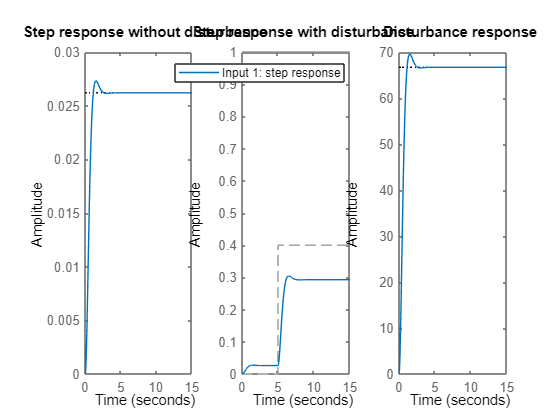

subplot(1,3,3);
step(Asf, [0; 100; 0], Csf, Dsf,1,t); % Bsf = [0; 100; 0]
title('Disturbance response');

## Conclusion A:

1)  When the system is subjected to input disturbances, the state feedback controller without integral control may not be able to reject the disturbances completely, leading to steady-state errors.

2) The state feedback controller doesn't always track the reference signal accurately due to its inherent steady-state error.

3) The response time of the variable state feedback controller is very good.

%% integral control
% a)
Ae = [Ag zeros(size(Ag(:,1))); Cg zeros(size(Cg(:,1)))];% Ae = [Ag 0; Cg 0]
Be = [Bg; zeros(size(Bg(1,:)))];% Be = [Bg; 0]
Ce = [Cg zeros(size(Cg(:,1)))];% Ce = [Cg 0]
De = [0];

% b)
system_order = length(Ae)

system_order = 4

M = ctrb(Ae, Be);
rank_of_M = rank(M)

rank_of_M = 4

N = obsv(Ae, Ce);
rank_of_N = rank(N)

rank_of_N = 3

% c)
desiredpoles_ext = [dominant' 10*real(dominant(1)) 20*real(dominant(1))];

% d)
K_e = acker(Ae, Be, desiredpoles_ext)

K_e = 	1.0e+03 *

    0.0619    1.1736    4.3893    1.6195


% e)
Asf_ext = Ae - Be * K_e;
B_r = [0; 0; 0; -1];
[numsf_ext, densf_ext] = ss2tf(Asf_ext, B_r, Ce, De);
SYS_ext = tf(numsf_ext, densf_ext);

%simulating system
figure(2);
subplot(1,3,1);
step(Asf_ext, B_r, Ce, De, 1, t);
title('Step response without disturbance');
axis([0 15 0 1.2]);
subplot(1,3,2);
lsim(Asf_ext, [0 0; 0 1; 0 0; -1 0], Ce, De, [input1' input2'], t);
title('Step response with disturbance');
legend('step response', 'disturbance signal')

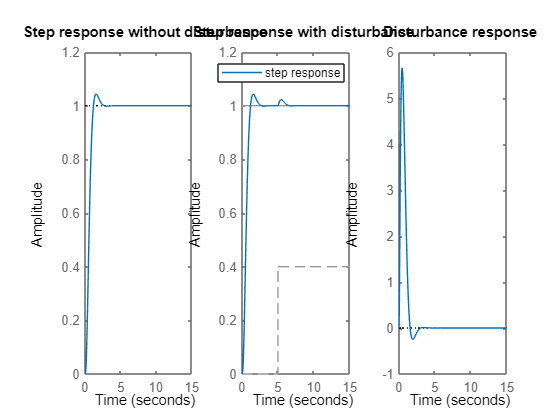

axis([0 15 0 1.2]);
subplot(1,3,3);
step(Asf_ext, [0; 100; 0; 0], Ce, De, 1, t);
title('Disturbance response');

## conclusion B:

1) In comparaison to a system without integral control the steady state error can be completely eliminated thanks to continuous integration of the error signal. 

2) Beacouse of the integal control 2nd system is capable of eliminating steady state error caused by the const. reference signals therefore offering better reference tracking.

3) the response time of an integral control system is generally longer then the pure variable feedback controller.

## Results of a simulink simulation:

1) Simulink model:

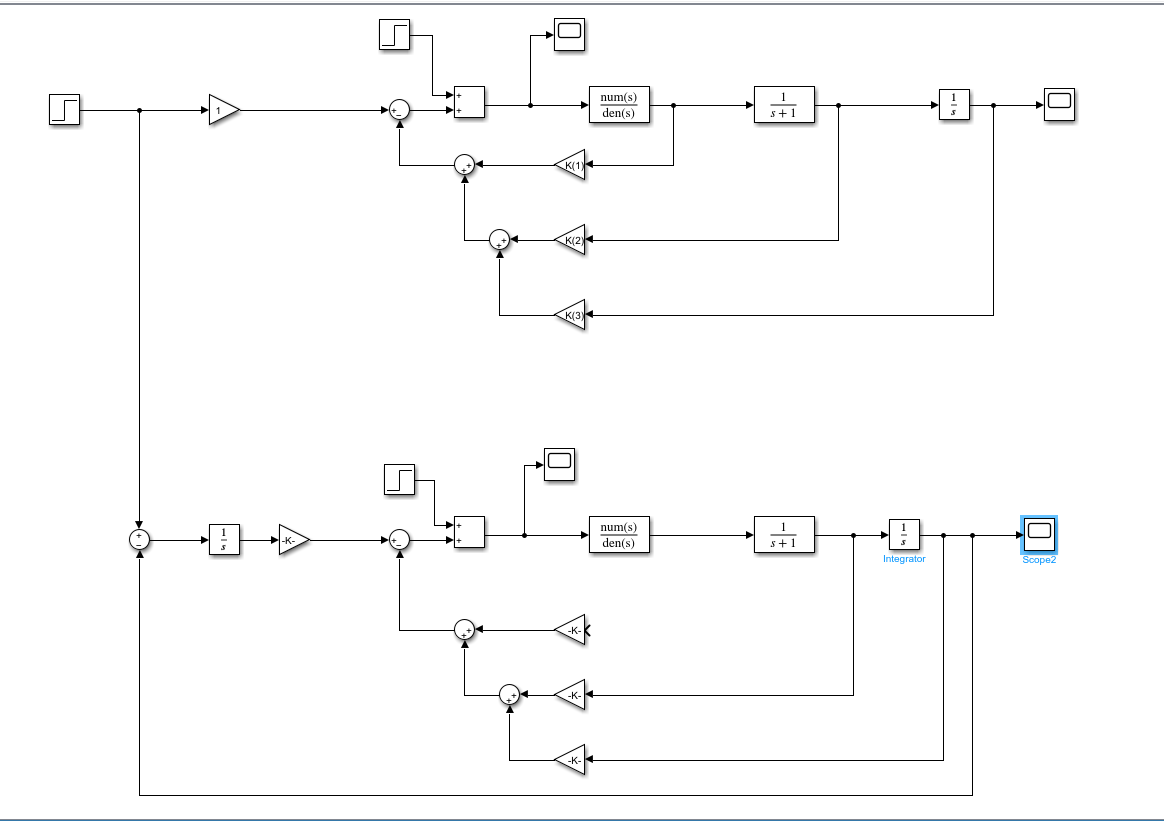

2) scope of a system without integral control:

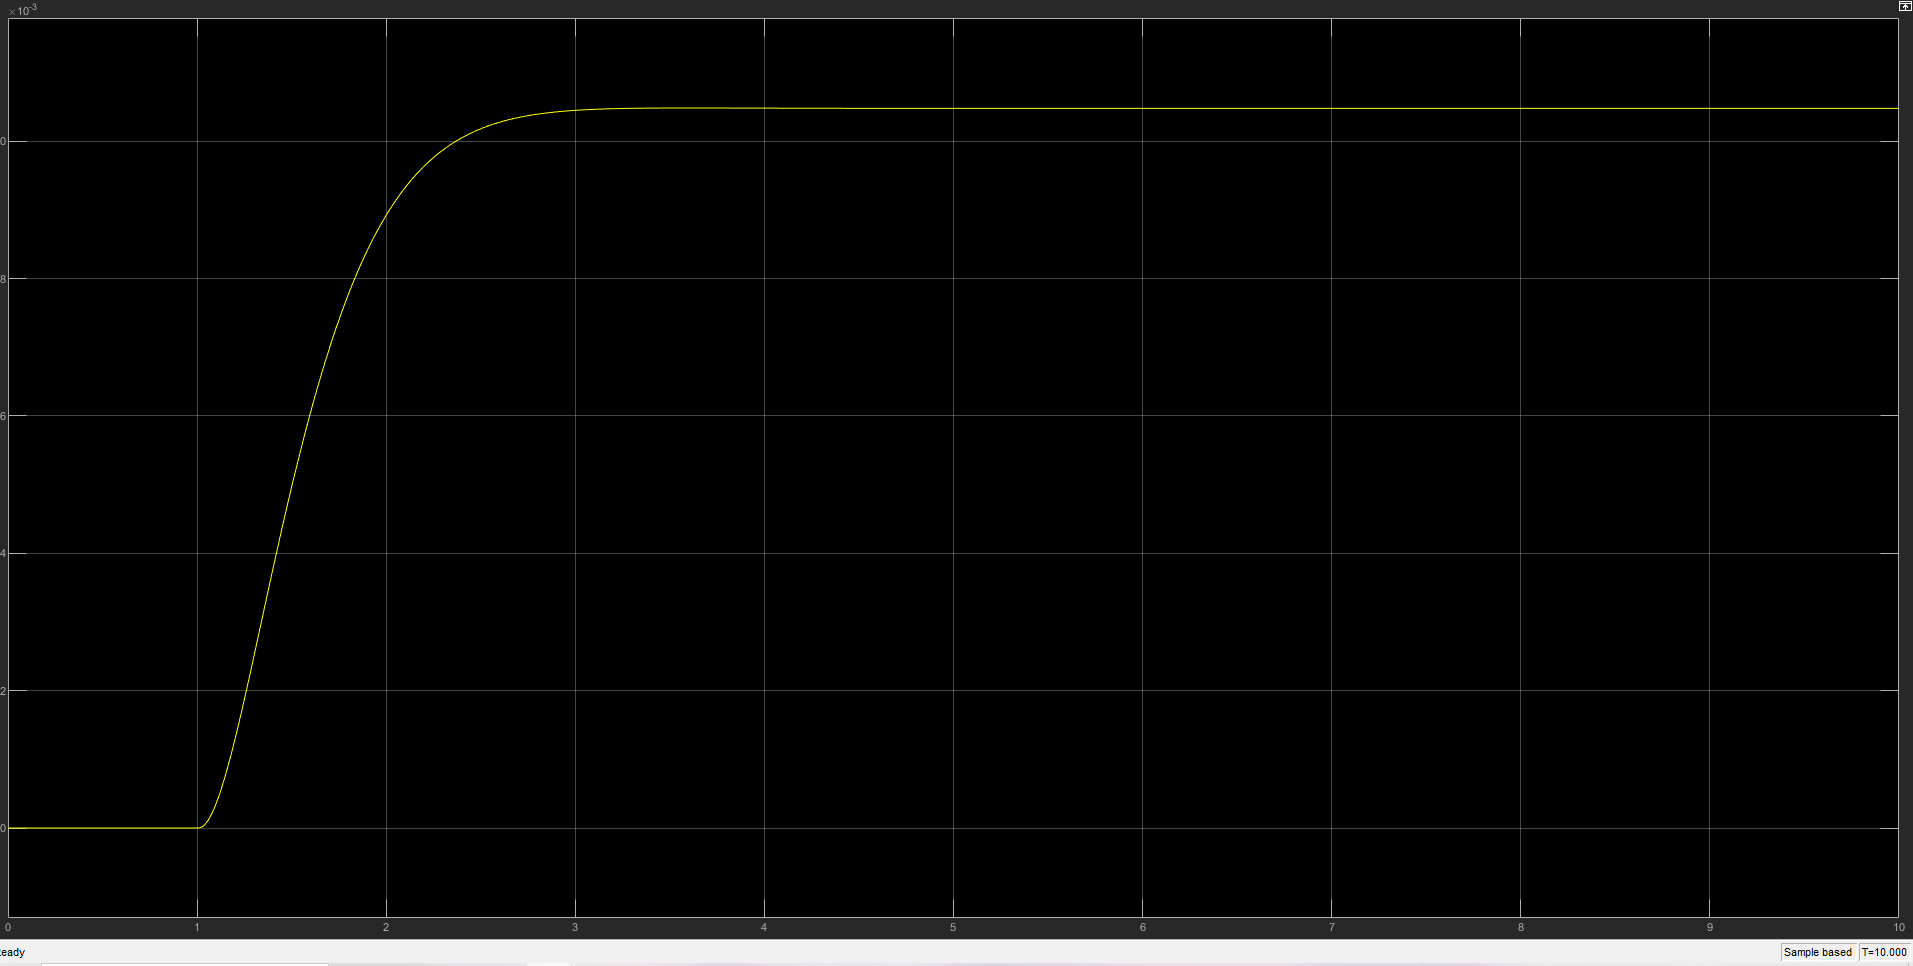

3) scope of a system with integral control: